# Modeling Mean Flight Speed

## 1. Import and create data

clear all; load('./data/dc_corr.mat'); load coastlines; addpath('functions/'); warning('off')

Convert the volumetric speed to a surface speed (`denss`)

for i=1:numel(dc)
    tmp=diff(double([0 max(0, (1:dc(i).levels).*dc(i).interval - dc(i).height )]))/1000;
    nb_bird=dc(i).dens .* repmat(tmp,size(dc(i).dens,1),1);
    dc(i).denss = sum(nb_bird,2);
    nb_bird(isnan(dc(i).ff))=0;
    dc(i).ffs = nansum(dc(i).ff.*nb_bird,2)./sum(nb_bird,2);
    dc(i).dd = mod(dc(i).dd,360);
    dc(i).dds = nansum(dc(i).dd.*nb_bird,2)./sum(nb_bird,2);
    dc(i).scoret = datenum(dc(i).time'-mean([dc(i).sunrise;dc(i).sunset])) ./ datenum(dc(i).sunrise-dc(i).sunset)*2;
end

Create the data structure `data`

dens_lim = 0;
ffs_lim = 0;
data=[];
uniqueDate = round(datenum(datetime(start_date-1:end_date-1)));
for i=1:numel(dc)
    id = dc(i).scoret(:)>=-1 & dc(i).scoret(:)<=1 & dc(i).denss>dens_lim & dc(i).ffs>ffs_lim;
    d=table();
    d.ff=dc(i).ffs(id);
    d.dd=dc(i).dds(id);
    d.dens=dc(i).denss(id);
    d.scoret = dc(i).scoret(id)';
    d.i_r=i*ones(sum(id),1);
    d.lat=dc(i).lat*ones(sum(id),1);
    d.lon=dc(i).lon*ones(sum(id),1);
    d.time = datenum(dc(i).time(id));
    tmp = round(datenum(dc(i).sunrise(id)))';
    [~,id]=ismember(tmp,uniqueDate);
    d.dateradar = sub2ind([numel(dc) numel(uniqueDate)],repmat(i,numel(tmp),1),id);
    data = [data ; d ];
end

clear d dens_lim 

## 2. Transformation of data

The row data of density present a very scew histogram

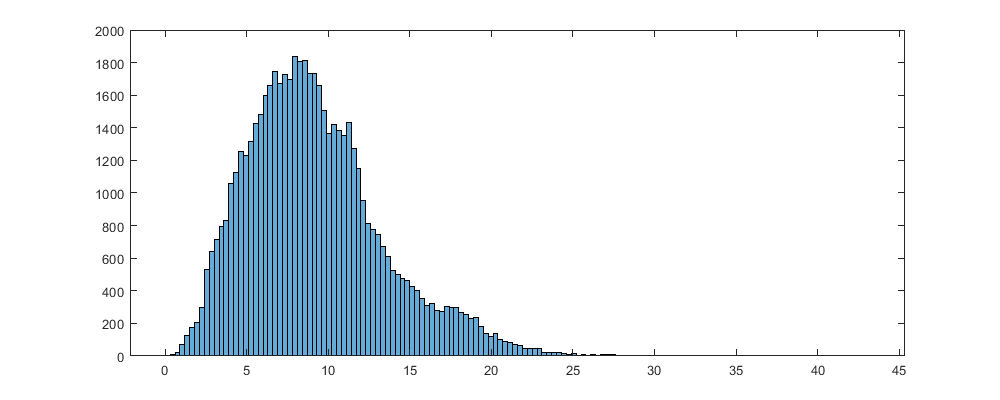

figure('position',[0 0 1000 400]); histogram(data.ff)

Power transform

for i=1:30
    tmp=data.ff.^(1/i);
    [~,tmp2(i)] = kstest((tmp-nanmean(tmp))./nanstd(tmp));
end
[~,pow_a]=max(tmp2);
disp(pow_a)

     3



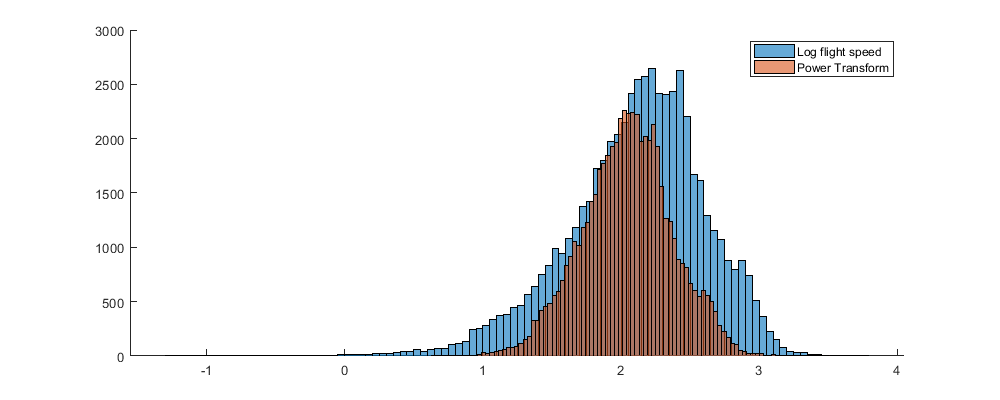

data.fftrans = data.ff.^(1/pow_a);

figure('position',[0 0 1000 400]); hold on;
histogram(log(data.ff))
histogram(data.fftrans)
legend('Log flight speed','Power Transform')

## 3. Amplitude, trend and cuve fitting

This section's purpuse is to find the value of *A* and paramaters of the polynomial *p* which fit best the data. We first find them seperatively and then perform a min-search of the equation combined.

Initialize *t* by simply finding the average of  each radar

S=zeros(numel(dc), 1);
for i=1:numel(dc)
    S(i)=mean(data.fftrans(data.i_r==i));
end
trend.p0=[[dc.lat]' [dc.lon]' ones(numel(dc),1)] \ S;
trend.t0 = ([dc.lat]'*trend.p0(1)+[dc.lon]'*trend.p0(2)+trend.p0(3));

Initialize A by simply finding the average of the night for each radar

ampli.A0=zeros(numel(dc), numel(uniqueDate));
for i=1:numel(ampli.A0)
    ampli.A0(i)=mean(data.fftrans(data.dateradar==i));
end
ampli.A0=ampli.A0-repmat(trend.t0,1,numel(uniqueDate));

Intialize the polyfit parameter by the residual of A for all radars. 

curve.nb_poly=6;
curve.p0 = polyfit(data.scoret,data.fftrans-trend.t0(data.i_r)-ampli.A0(data.dateradar),curve.nb_poly);

Performing an optimazation of the amplitude and polyfit parameter combined. 

rmse = @(x) nansum( ( pred3(x,numel(dc),numel(uniqueDate),curve.nb_poly,data,dc)  - data.fftrans ).^2 );
x = fminsearch(rmse,[trend.p0(:);ampli.A0(:);curve.p0(:)],optimset('MaxFunEvals',1000));

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1290.733644 



trend.p = x(1:3);
ampli.A = reshape(x(3+(1:numel(dc)*numel(uniqueDate))),numel(dc),numel(uniqueDate));
curve.p = x(end-curve.nb_poly:end);

Figure

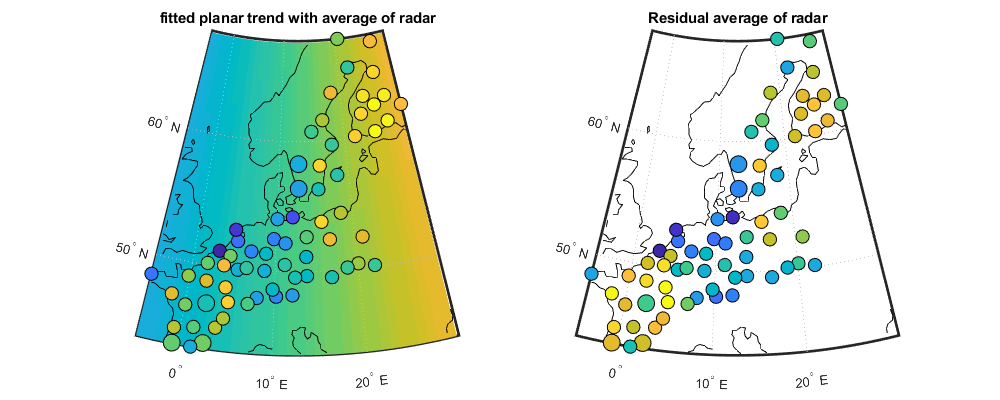

trend.t = ([dc.lat]'*trend.p(1)+[dc.lon]'*trend.p(2)+trend.p(3));

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
[LAT,LON] = meshgrid(min([dc.lat]):max([dc.lat]),min([dc.lon]):max([dc.lon]));
surfm(LAT,LON,LAT*trend.p(1)+LON*trend.p(2)+trend.p(3))
plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,S,'filled','MarkerEdgeColor','k'); title('fitted planar trend with average of radar'); 
subplot(1,2,2); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,S-trend.t,'filled','MarkerEdgeColor','k'); title('Residual average of radar');

The average of each radar during the study period shows a strong NS increase. This is expected as the migrant tion.... 

The residual shows more the coridor of migration with lower migration density along the FR-NL coast, and along the Alps. Another strange effect is the drastic change between Sweden and Finland. Why? 

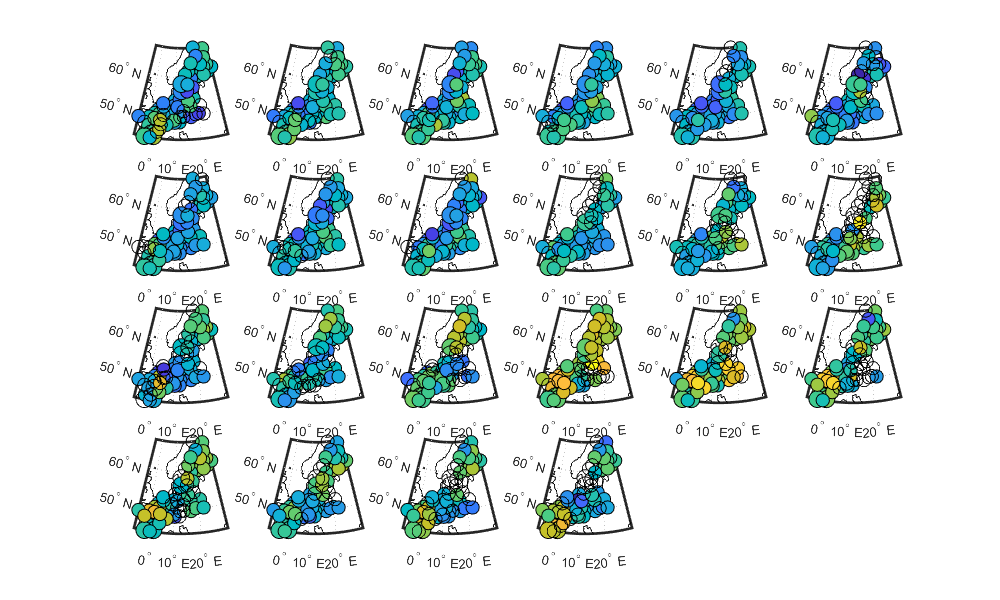

figure('position',[0 0 1000 600]);  c_caxis=[min(ampli.A(:)) max(ampli.A(:))];
for i = 1:numel(uniqueDate)
    subplot(4,6,i); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,ampli.A(:,i),'filled','MarkerEdgeColor','k');
    caxis(c_caxis);
end

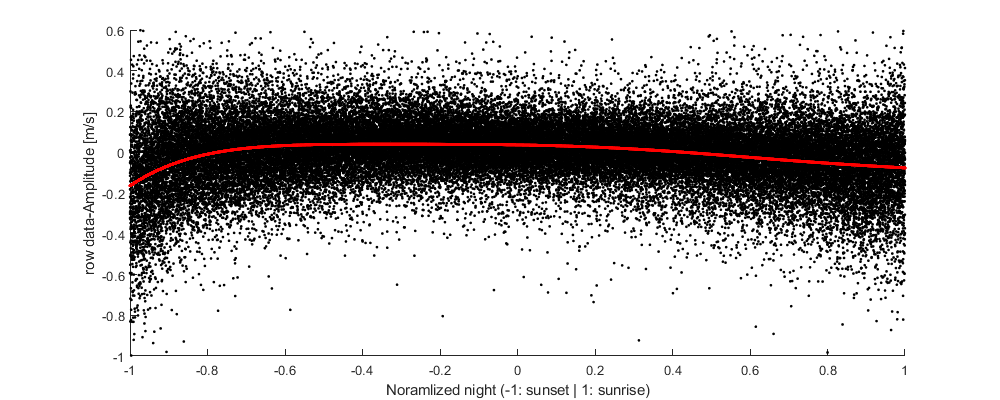

figure('position',[0 0 1000 400]); hold on; plot(data.scoret,data.fftrans-trend.t(data.i_r)-ampli.A(data.dateradar),'.k'); plot(data.scoret, polyval( curve.p, data.scoret ),'.r'); ylim([-1 .6])
xlabel('Noramlized night (-1: sunset | 1: sunrise)'); ylabel('row data-Amplitude [m/s]')

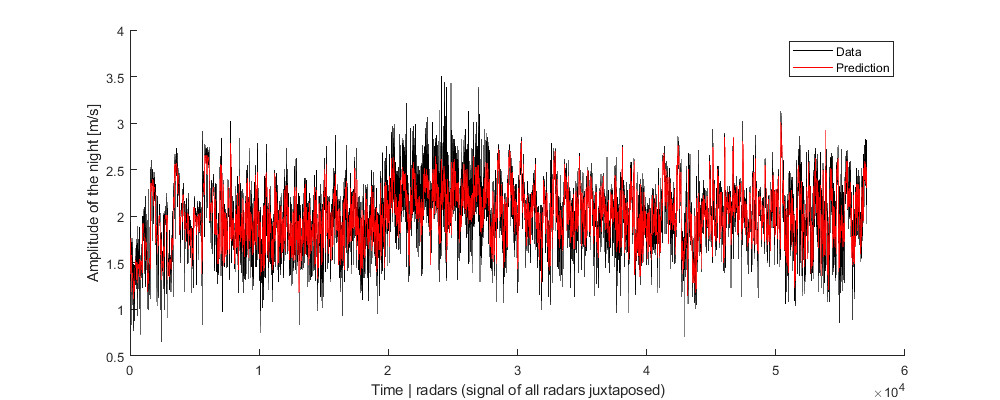

figure('position',[0 0 1000 400]); hold on; plot(data.fftrans,'k'); plot(pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'r'); 
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [m/s]'); legend('Data','Prediction')

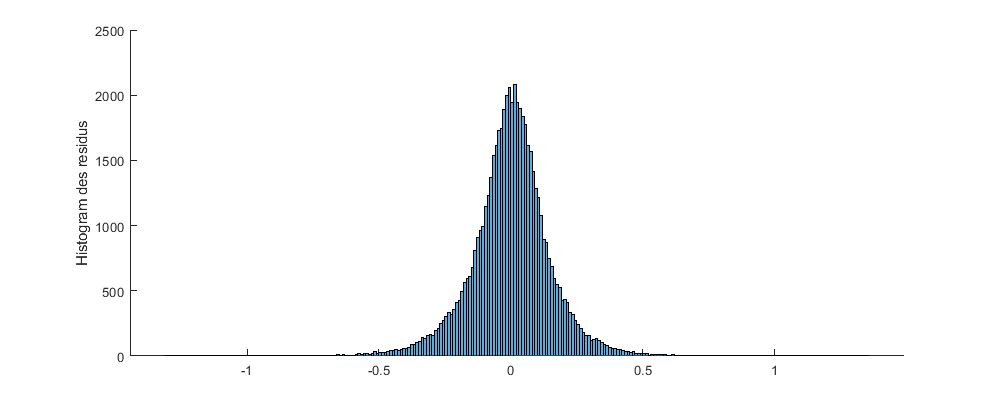

figure('position',[0 0 1000 400]); hold on; ylabel('Histogram des residus')
histogram(data.fftrans-pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc)); 

## 4. Kriging Amplitude

## 4.1 Normal Score

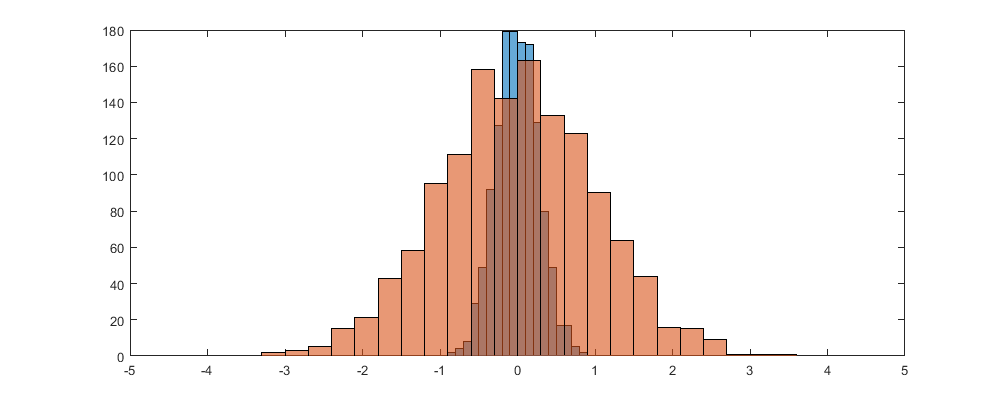

ampli.ns = nscore(ampli.A(:));
ampli.An = ampli.ns.forward(ampli.A);

figure('position',[0 0 1000 400]); hold on; histogram(ampli.A) ; histogram(ampli.An); box on;xlim([-5 5])

Buliding the distance

Dtime_sf=squareform(pdist(repelem(uniqueDate',numel(dc),1)));
Ddist_sf=squareform(pdist(repmat([[dc.lat]' [dc.lon]'], numel(uniqueDate),1),@lldistkm));

ampli.isnanA=isnan(ampli.An);
ampli.Dtime_sf=Dtime_sf(~ampli.isnanA,~ampli.isnanA);
ampli.Ddist_sf=Ddist_sf(~ampli.isnanA,~ampli.isnanA);
ampli.An=ampli.An(~ampli.isnanA)-nanmean(ampli.An(:));

## 4.2 Empirical ampli.cov.parmriogram

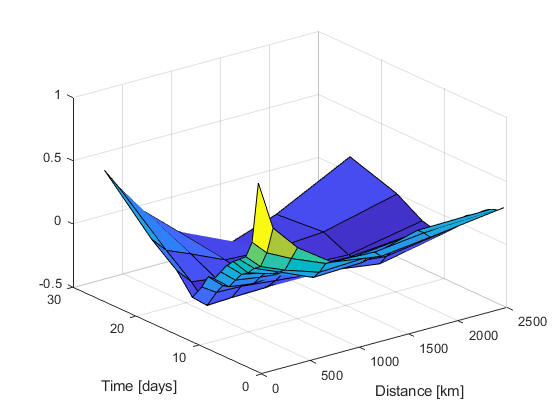

ampli.cov.emp = bsxfun(@times, ampli.An', ampli.An);

ampli.cov.d=[0 1 300 500 1000 1500 2000 3000];
ampli.cov.t=[0 1 2 3 4 5 6 7 8 9 10 12 15 20 30]; 
[ampli.cov.D,ampli.cov.T] = meshgrid(ampli.cov.d(1:end-1)+diff(ampli.cov.d)/2,ampli.cov.t(1:end-1)+diff(ampli.cov.t)/2);
ampli.cov.emp_grid=nan(size(ampli.cov.D));
for i_t=1:numel(ampli.cov.t)-1
    for i_d=1:numel(ampli.cov.d)-1
        id = ampli.Dtime_sf>=ampli.cov.t(i_t) & ampli.Dtime_sf<ampli.cov.t(i_t+1) & ampli.Ddist_sf>=ampli.cov.d(i_d) & ampli.Ddist_sf<ampli.cov.d(i_d+1);
        ampli.cov.emp_grid(i_t,i_d) = mean( ampli.cov.emp(id) );
    end
end
figure;surf(ampli.cov.D,ampli.cov.T,ampli.cov.emp_grid); xlabel('Distance [km]'); ylabel('Time [days]')

## 4.3 Variogram fitting

The variogram fitted is composed of a nugget and Gneiting model. The data are filtered by a maximum distance and time and reduce the computational cost and overfitting long-distance/time lag. First a gloabl optimzer is used (multi-start) and then a local optimizer refine the result

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
Gneiting_fit = @(parm) parm(2).*Gneiting(ampli.cov.D(:),ampli.cov.T(:),parm(3),parm(4),parm(5),parm(6),parm(7));

ampli.cov.parm0 =[.5 .5 500 5 .5 .5 .5];
ampli.cov.parm_min=[0 0 0.0001 0 0 0 0 ]';
ampli.cov.parm_max=[nancov(ampli.An) nancov(ampli.An) 3000 10 1 1 1]';

rmse = @(parm) sum( ( Gneiting_fit(parm) - ampli.cov.emp_grid(:) ).^2 );
ampli.cov.parm = fmincon(rmse,ampli.cov.parm0,[],[],[],[],ampli.cov.parm_min,ampli.cov.parm_max,[]);% ,optimset('PlotFcn',@optimplotfval)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

ampli.cov.parm(1) = nancov(ampli.An)-ampli.cov.parm(2);
sprintf('%.3f ',ampli.cov.parm)

ans = '0.000 1.000 630.399 2.157 1.000 0.188 0.000 '

Figure

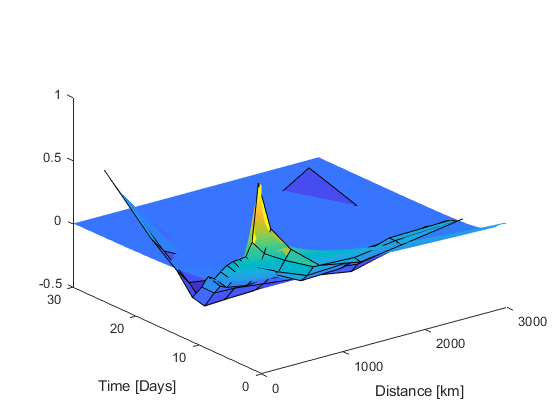

[tmpD,tmpT] = meshgrid(ampli.cov.d(1):1:ampli.cov.d(end),ampli.cov.t(1):0.1:ampli.cov.t(end));
tmpCOV=ampli.cov.parm(2).*Gneiting(tmpD(:), tmpT(:), ampli.cov.parm(3), ampli.cov.parm(4), ampli.cov.parm(5), ampli.cov.parm(6), ampli.cov.parm(7));
tmpCOV=reshape(tmpCOV,size(tmpD,1),size(tmpD,2));
tmpCOV(1)=tmpCOV(1)+ampli.cov.parm(1);
figure; hold on;
s=surf(tmpD,tmpT,tmpCOV);
surf(ampli.cov.D,ampli.cov.T,ampli.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');
s.EdgeColor='none'; view(3)

## 4.4 Estimate Amplitude with kriging

ampli.cov.C = diag(repmat(ampli.cov.parm(1),size(ampli.Ddist_sf,1),1)) +ampli.cov.parm(2).*Gneiting(ampli.Ddist_sf,ampli.Dtime_sf, ampli.cov.parm(3), ampli.cov.parm(4), ampli.cov.parm(5), ampli.cov.parm(6), ampli.cov.parm(7));

[~,R] = meshgrid(uniqueDate,1:numel(dc));
R=R(~ampli.isnanA);

ampli.An_est=nan(size(ampli.An));
ampli.An_sig=nan(size(ampli.An));

for i=1:numel(dc)

    neigh=R~=i;
    sim=find(~neigh);
    %i_neigh(Dist_km_sf(i,:)<100)=false;
    
    for i_sim=1:numel(sim)
        lambda = ampli.cov.C(neigh,neigh)  \  ampli.cov.C(neigh,sim(i_sim));
        ampli.An_est(sim(i_sim)) =  lambda' * ampli.An(neigh);
        ampli.An_sig(sim(i_sim)) = sqrt(ampli.cov.parm(1) + ampli.cov.parm(2) - lambda' * ampli.cov.C(neigh,sim(i_sim)));
    end
end



Figure;

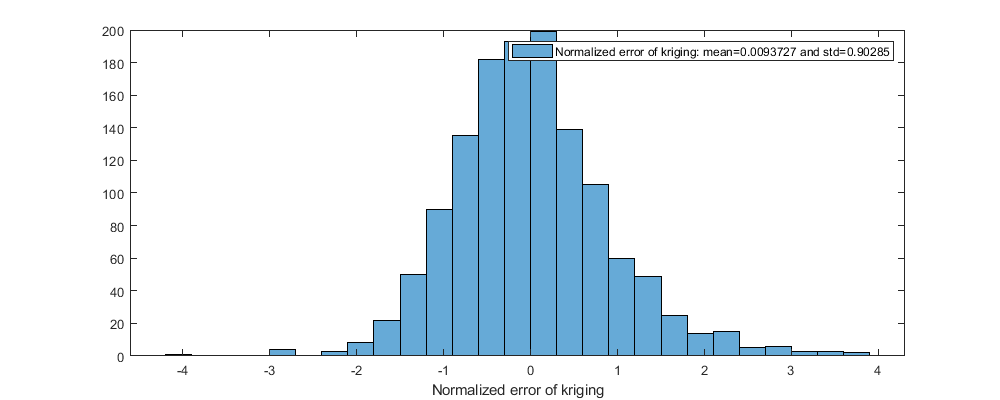

figure('position',[0 0 1000 400]); histogram((ampli.An_est-ampli.An)./ampli.An_sig)
xlabel('Normalized error of kriging')
legend(['Normalized error of kriging: mean=' num2str(mean((ampli.An_est-ampli.An)./ampli.An_sig)) ' and std=' num2str(std((ampli.An_est-ampli.An)./ampli.An_sig))]);

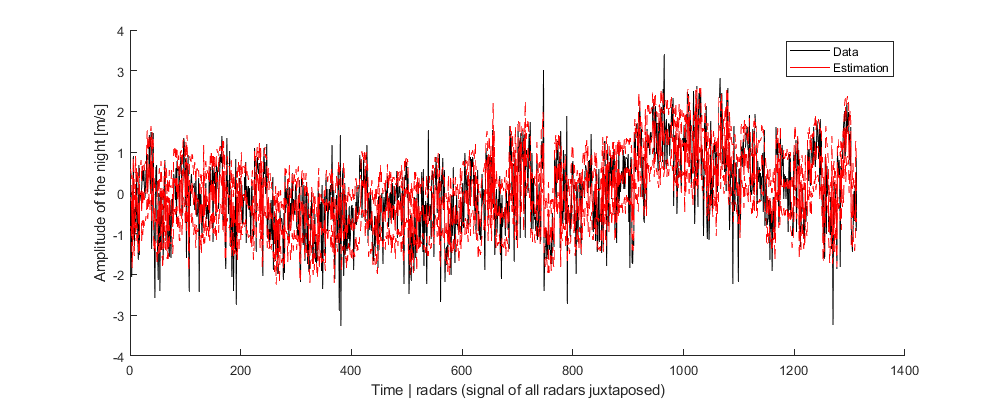

figure('position',[0 0 1000 400]); hold on;
plot(ampli.An,'k');
plot(ampli.An_est,'r')
plot(ampli.An_est-ampli.An_sig,'--r')
plot(ampli.An_est+ampli.An_sig,'--r')
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [m/s]'); legend('Data','Estimation')

## 4.5 Back-transform

ampli.A_est = nan(size(ampli.A));
ampli.A_est(~ampli.isnanA) = ampli.ns.inverse(ampli.An_est);

ampli.A_sig = nan(size(ampli.A,1),size(ampli.A,2),7);
ampli.A_sig(~repmat(ampli.isnanA,1,1,7)) = ampli.ns.inverse( repmat(ampli.An_est,1,7) + bsxfun(@times,ampli.An_sig,(-3:3)) );

c_caxis=[min(ampli.A(:)) max(ampli.A(:))];
figure('position',[0 0 1000 600]);
for i = 1:numel(uniqueDate)
    subplot(4,6,i); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,ampli.A(:,i),'filled','MarkerEdgeColor','k'); caxis(c_caxis)
end

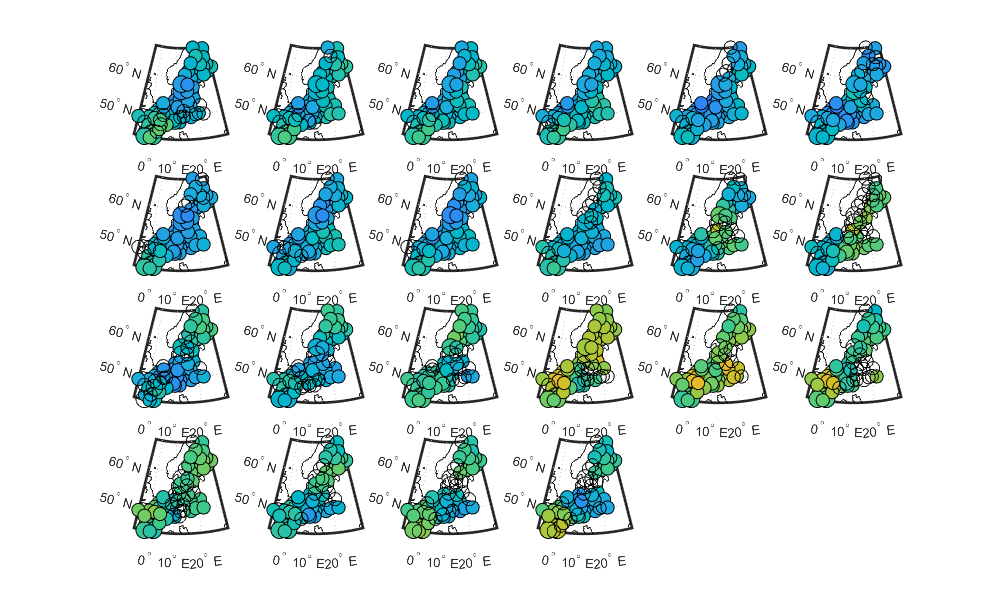

figure('position',[0 0 1000 600]); 
for i = 1:numel(uniqueDate)
    subplot(4,6,i); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,ampli.A_est(:,i),'filled','MarkerEdgeColor','k'); caxis(c_caxis)
end

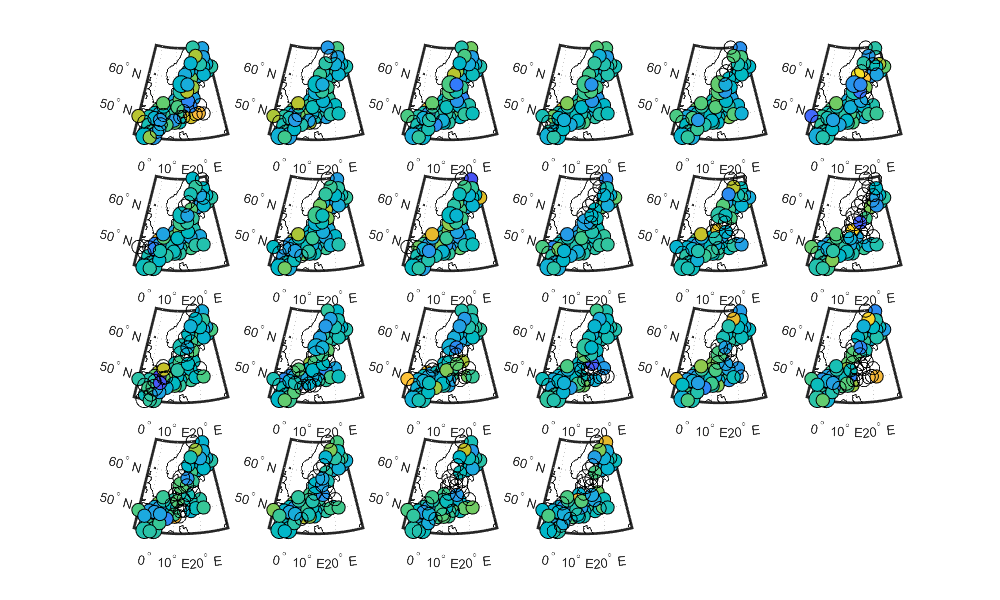

figure('position',[0 0 1000 600]); 
for i = 1:numel(uniqueDate)
    subplot(4,6,i); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,ampli.A_est(:,i)-ampli.A(:,i),'filled','MarkerEdgeColor','k'); caxis(c_caxis)
end

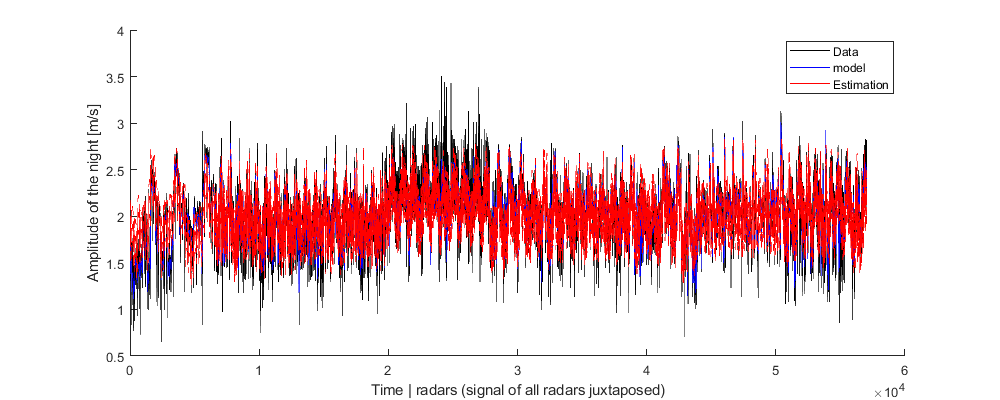

figure('position',[0 0 1000 400]); hold on; 
plot(data.fftrans,'k'); 
plot(pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'b');
plot(pred3([trend.p(:);ampli.A_est(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'r'); 
plot(pred3([trend.p(:);reshape(ampli.A_sig(:,:,3),[],1);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'--r'); 
plot(pred3([trend.p(:);reshape(ampli.A_sig(:,:,5),[],1);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'--r'); 

xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [m/s]'); legend('Data','model','Estimation')

## 5. Residus

res.r = data.fftrans-pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc);

% A=nan(numel(dc),numel(uniqueDate));
% for i=1:numel(A)
%     id=data.dateradar==i;
%     fun = @(a) nanmean( (a*data.scoret(id)-res.r(id)).^2 );
%     A(i)=fminsearch(fun,0);
%     res.r2(id) = res.r(id)-A(i)*data.scoret(id);
% end


## 5.1 Normalization residu

Normalized the noise according to the night

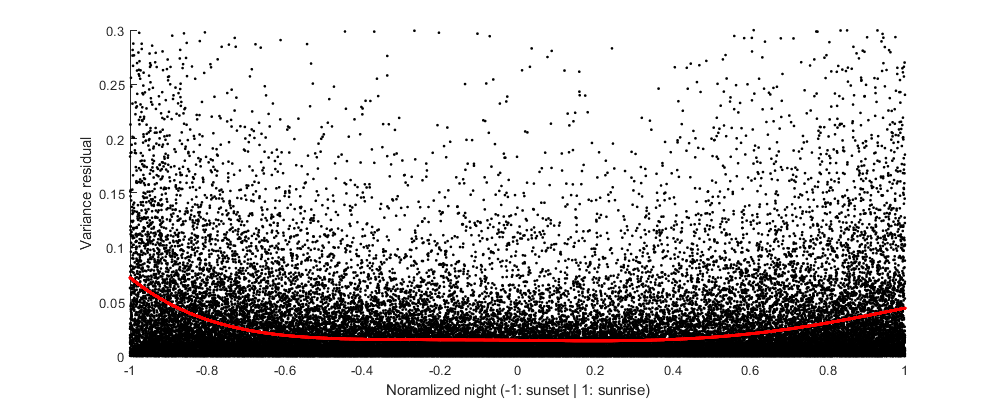

res.p = polyfit(data.scoret,res.r(:).^2,5);

figure('position',[0 0 1000 400]); hold on;
plot(data.scoret,res.r.^2,'.k'); plot(data.scoret,polyval(res.p,data.scoret),'.r'); ylim([0 .3]); 
xlabel('Noramlized night (-1: sunset | 1: sunrise)'); ylabel('Variance residual')

Normalized the residu

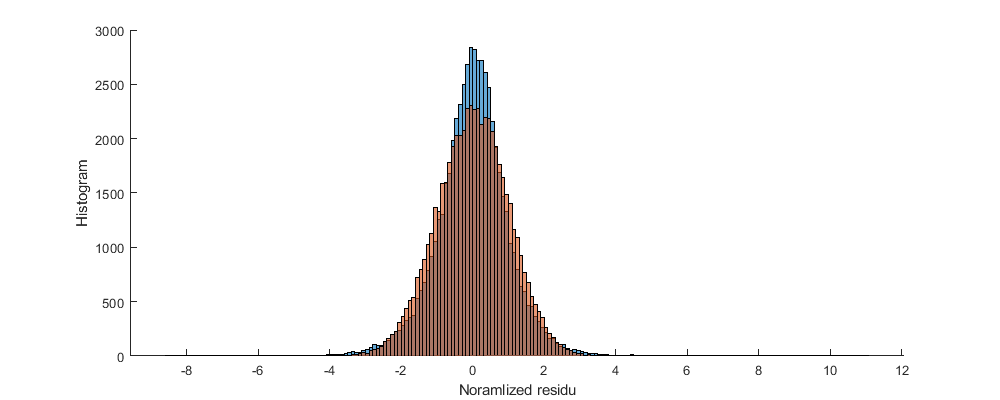

res.ns = nscore(res.r(:)./sqrt(polyval(res.p,data.scoret)));
res.rn = res.ns.forward(res.r(:)./sqrt(polyval(res.p,data.scoret)));

figure('position',[0 0 1000 400]); hold on; histogram(res.r./sqrt(polyval(res.p,data.scoret))) ; histogram(res.rn)
xlabel('Noramlized residu'); ylabel('Histogram')

## 5.2 Built matrix of distance

Built the matrix of distances of the data. Distence (or difference) in lattitude, longitude, time and value. 

res.D=table();
for i=1:numel(uniqueDate)
    d=table();
    
    id  = find(ismember( data.dateradar, sub2ind([numel(dc), numel(uniqueDate)],1:numel(dc),i*ones(1,numel(dc)))));

    d.Ddist = reshape(Ddist_sf(data.i_r(id),data.i_r(id)'),[],1);
    d.Dtime = reshape(squareform(pdist(data.time(id))),[],1);
    d.Did1 = repmat(id,numel(id),[]);
    d.Did2 = repelem(id,numel(id));
    
    res.D=[res.D ; d];
end

## 5.3 Empirical Variogram

res.cov.d=[0 50 100 150 200 250 300 600 1000 1500 2000 3000];
res.cov.t=[0 .01 .02 .05 .07 .1 .15 .2 .25 .3 .35 .4 .45]; 
[res.cov.D,res.cov.T]=meshgrid(res.cov.d(1:end-1)+diff(res.cov.d)/2,res.cov.t(1:end-1)+diff(res.cov.t)/2);

res.cov.emp_grid=nan(size(res.cov.D));

for i_d=1:numel(res.cov.d)-1
    id1 = find(res.D.Ddist>=res.cov.d(i_d) & res.D.Ddist<res.cov.d(i_d+1));
    for i_t=1:numel(res.cov.t)-1
        id2 = id1(res.D.Dtime(id1)>=res.cov.t(i_t) & res.D.Dtime(id1)<res.cov.t(i_t+1));
        res.cov.emp_grid(i_t,i_d)=mean(res.rn(res.D.Did1(id2)) .* res.rn(res.D.Did2(id2)));
    end
end

Figure

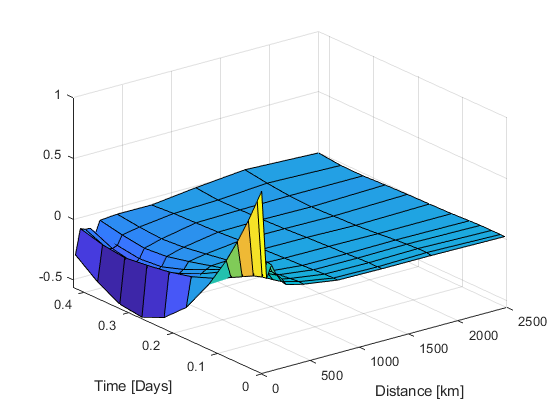

figure; surf(res.cov.D,res.cov.T,res.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');

The empirical variogram of the residu shows a very intersting effect.

[...] 

The empirical variogram of the absolute value of the residu confirms our explanation with the lowest variance.

## 5.4 Calibrate ampli.cov.parmriance 

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
Gneiting_fit = @(parm) parm(2).*Gneiting(res.cov.D(:),res.cov.T(:),parm(3),parm(4),parm(5),parm(6),parm(7));

res.cov.parm0 =[.5 .5 500 5 .5 .5 .5];
res.cov.parm_min=[0 0 0.0001 0 0 0 0 ]';
res.cov.parm_max=[nancov(res.rn) res.cov.emp_grid(1) 3000 10 1 1 1]';

rmse = @(parm) sum( ( Gneiting_fit(parm) - res.cov.emp_grid(:) ).^2 );
res.cov.parm = fmincon(rmse,res.cov.parm0,[],[],[],[],res.cov.parm_min,res.cov.parm_max,[]);% ,optimset('PlotFcn',@optimplotfval)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

res.cov.parm(1) = nancov(res.rn)-res.cov.parm(2);
sprintf('%.3f ',res.cov.parm)

ans = '0.069 0.931 117.339 0.044 1.000 0.437 0.000 '

Figure

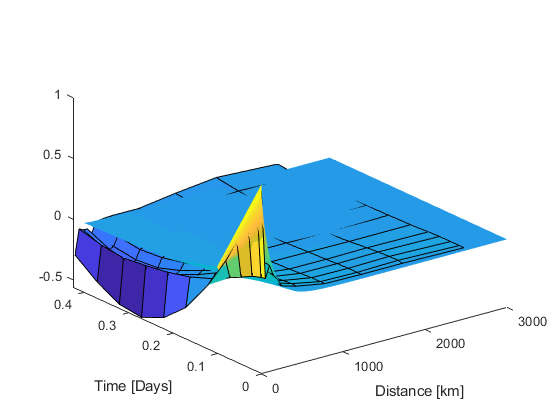

[tmpD,tmpT] = meshgrid(res.cov.d(1):1:res.cov.d(end),res.cov.t(1):0.1:res.cov.t(end));
tmpCOV=res.cov.parm(2).*Gneiting(tmpD(:), tmpT(:), res.cov.parm(3), res.cov.parm(4), res.cov.parm(5), res.cov.parm(6), res.cov.parm(7));
tmpCOV=reshape(tmpCOV,size(tmpD,1),size(tmpD,2));
tmpCOV(1)=tmpCOV(1)+res.cov.parm(1);
figure; hold on;
s=surf(tmpD,tmpT,tmpCOV);
surf(res.cov.D,res.cov.T,res.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');
s.EdgeColor='none'; view(3)

## 5.5 Kriging residual

res.cov.C = res.cov.parm(2).*Gneiting(res.D.Ddist, res.D.Dtime, res.cov.parm(3), res.cov.parm(4), res.cov.parm(5), res.cov.parm(6), res.cov.parm(7));
res.cov.C = sparse(res.D.Did1,res.D.Did2,res.cov.C);
res.cov.C = res.cov.C + spdiags(repmat(res.cov.parm(1),size(res.cov.C,1),1),0,size(res.cov.C,1),size(res.cov.C,2));

res.rn_est=nan(size(res.rn));
res.rn_sig=nan(size(res.rn));

for i_d=1:numel(uniqueDate)
    neigh  = find(ismember( data.dateradar, sub2ind([numel(dc), numel(uniqueDate)],1:numel(dc),i_d*ones(1,numel(dc)))));

    for i_s=1:numel(neigh)
        
        neigh_s = neigh(data.dateradar(neigh)~=data.dateradar(neigh(i_s)));
        Cab = full(res.cov.C(neigh_s,neigh(i_s)));
        neigh_s=neigh_s(Cab>.1);

            % Simple
            lambda = res.cov.C(neigh_s,neigh_s) \ res.cov.C(neigh_s,neigh(i_s));
            res.rn_est(neigh(i_s)) =  lambda' * res.rn(neigh_s);
            res.rn_sig(neigh(i_s)) = sqrt(res.cov.parm(1) + res.cov.parm(2) - lambda' * res.cov.C(neigh_s,neigh(i_s)));
            
            % Ordinary
            % lambda = [Caa ones(size(Caa,1),1); ones(1,size(Caa,1)) 0] \ [ Cab ; 1];
            % res.rn_est(i) =  lambda(1:end-1)' * res.rn(neigh);
            % res.rn_sig(i) = res.cov.parm(1) + res.cov.parm(2) - lambda(1:end-1)' * Cab - lambda(end);
            
            % figure; hold on;
            % scatter3(data.lon(i),data.lat(i),data.time(i),'r','filled')
            % % scatter3(data.lon(neigh),data.lat(neigh),data.time(neigh),[],Cab,'filled')
            %  scatter3(data.lon(neigh),data.lat(neigh),data.time(neigh),[],lambda,'filled')
    end
end

Figure

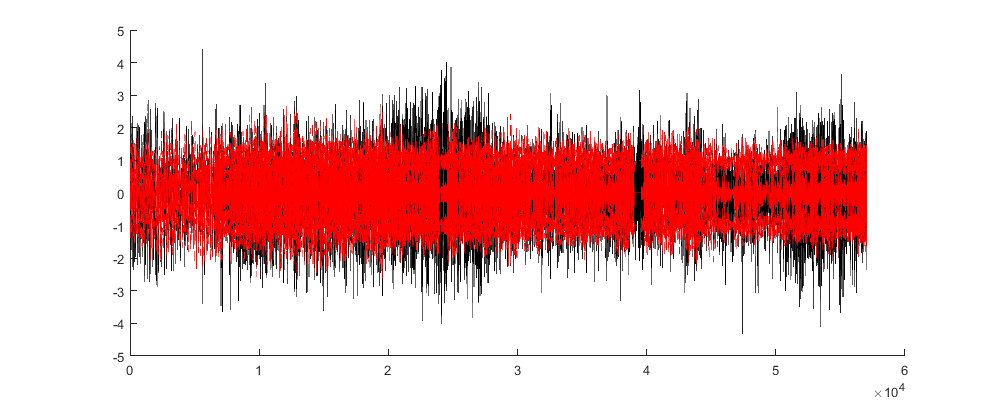

figure('position',[0 0 1000 400]); hold on;
plot(res.rn,'k');
plot(res.rn_est,'r')
plot(res.rn_est-res.rn_sig,'--r')
plot(res.rn_est+res.rn_sig,'--r')

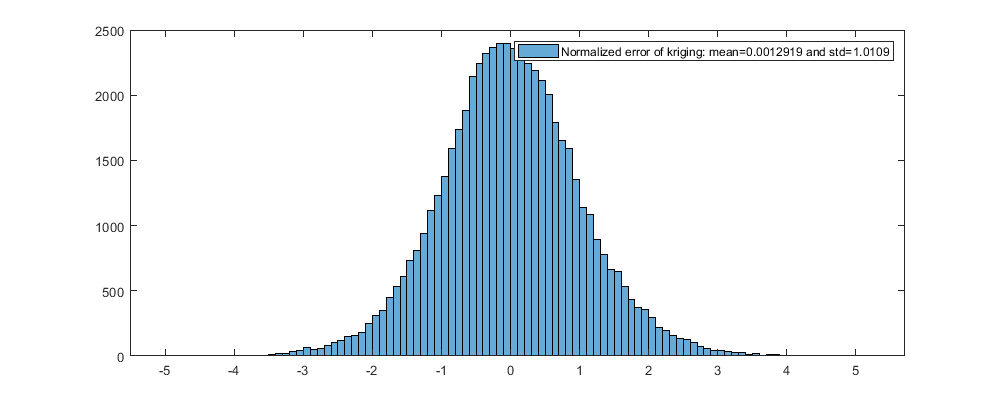

err_norm = (res.rn_est-res.rn)./(res.rn_sig);
figure('position',[0 0 1000 400]); histogram( err_norm );
legend(['Normalized error of kriging: mean=' num2str(mean((res.rn_est-res.rn)./res.rn_sig)) ' and std=' num2str(std((res.rn_est-res.rn)./res.rn_sig))]);

## 5.6 Back Normalized

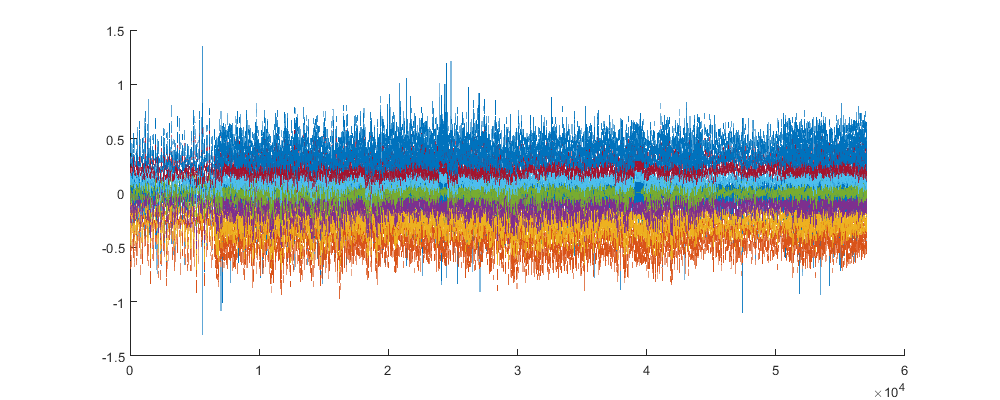

res.r_est = res.ns.inverse(bsxfun(@times,sqrt(polyval(res.p,data.scoret)),bsxfun(@plus , res.rn_est, res.rn_sig*(-3:3))));

figure('position',[0 0 1000 400]); hold on;
plot(res.r)
plot(res.r_est,'--')

## 6. Assemble the estimation

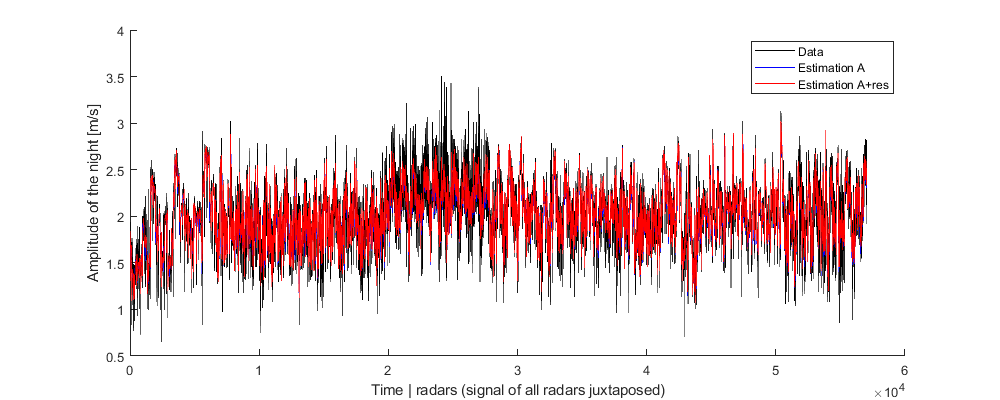

data.fftrans_est = pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc)+res.r_est(:,4);

data.ff_est = (data.fftrans_est).^pow_a;

figure('position',[0 0 1000 400]); hold on;
plot(data.fftrans,'k');
plot(pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'b');
plot(data.fftrans_est,'r');
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [m/s]'); legend('Data','Estimation A','Estimation A+res')

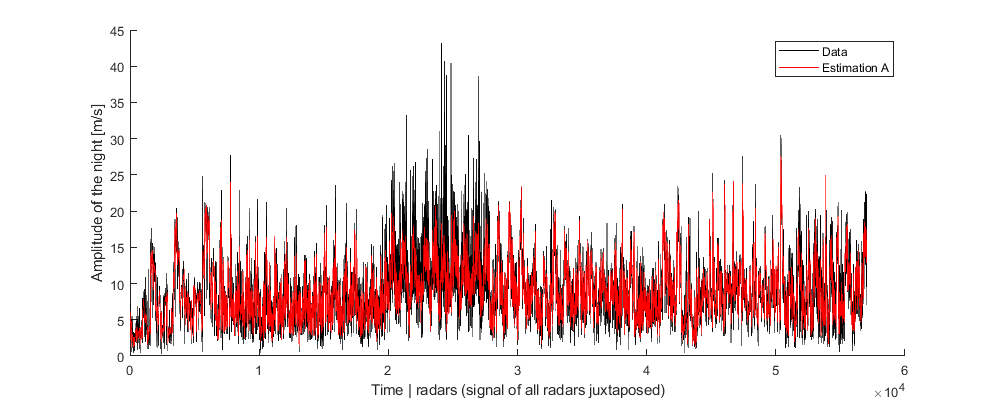


figure('position',[0 0 1000 400]); hold on;
plot(data.ff,'k');
plot(data.ff_est,'r');
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [m/s]'); legend('Data','Estimation A','Estimation A+res')

sqrt(mean( (pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc)-data.fftrans ).^2 ))

ans = 0.1504

sqrt(mean( (data.fftrans_est-data.fftrans ).^2 ))

ans = 0.1387

sqrt(mean( (data.fftrans_est-data.ff ).^2 ))

ans = 8.1912

## 7. Save

save('data/FlightSpeed_modelInf.mat','data','trend','ampli','curve','res','pow_a','-v7.3')
% load('data/FlightSpeed_modelInf.mat')